participants(1) = load("..\..\results\p-05\rev-02\task_results.mat");
participants(2) = load("..\..\results\p-06\rev-02\task_results.mat");
participants(3) = load("..\..\results\p-07\rev-02\task_results.mat")

participants = 1×3 struct array with fields:
    task_results


list_length = length(participants);

## Aggregate RMSE (Control)

boxplot of all subject RMSEs for all trials

ans = "AD test: 1"

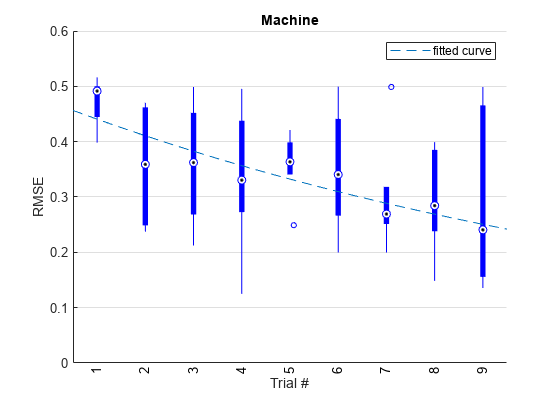

plot_aggregate_rmse_ctrl(participants, 1, "Machine", 'b', '--');

ans = "AD test: 1"

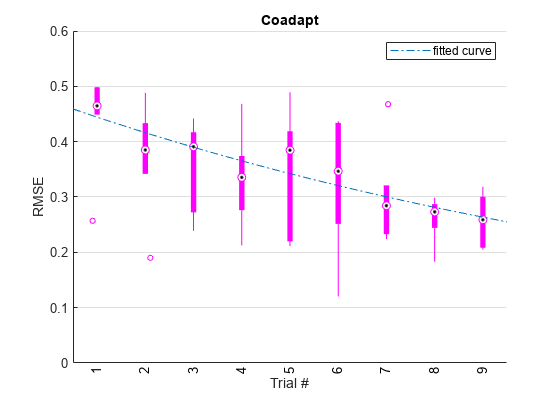

% exportgraphics(gcf,'vectorfig.pdf','ContentType','vector')
plot_aggregate_rmse_ctrl(participants, 2, "Coadapt", 'm', '-.');

ans = "AD test: 1"

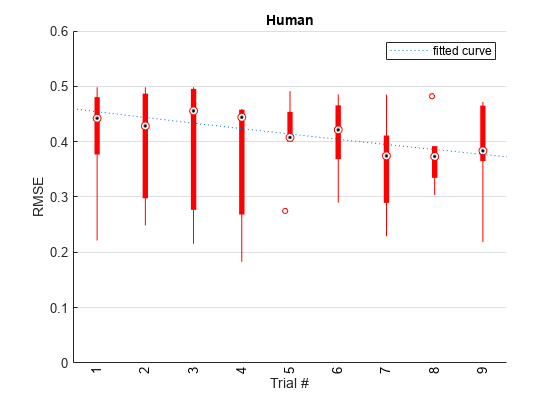

plot_aggregate_rmse_ctrl(participants, 3, "Human", 'r', ':');

## Aggregate RMSE (Experimental)

ans = "AD test: 1"

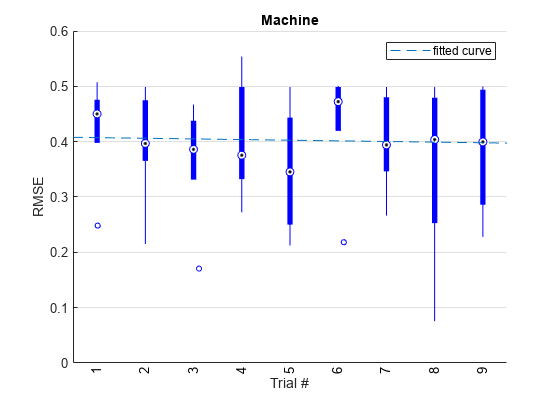

plot_aggregate_rmse_expl(participants, 1, "Machine", 'b', '--');

ans = "AD test: 0"

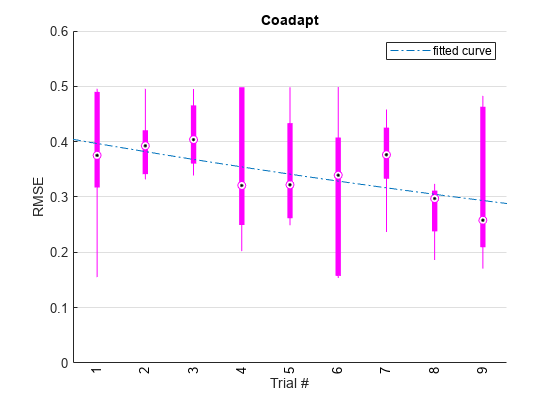

plot_aggregate_rmse_expl(participants, 2, "Coadapt", 'm', '-.');

ans = "AD test: 1"

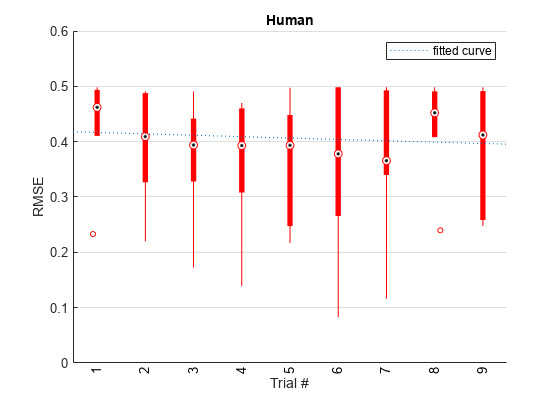

plot_aggregate_rmse_expl(participants, 3, "Human", 'r', ':');

## Learning Rate Comparison (Control)

AD test for group A: 1, p=0.002
AD test for group B: 0, p=0.794
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=0
	p=1.000
	N=6
Difference is not significant


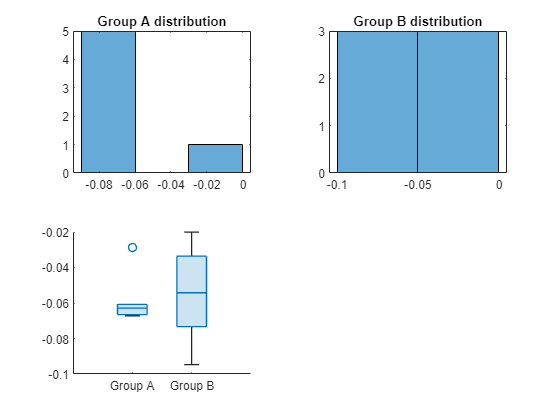

MODEL_SEED = [0.6, -0.2];

task_coeffs = [];
for task_idx = 1:3
    rmse_tbt_aggregate = [];
    for i=1:list_length
        rmse_tbt_aggregate = [rmse_tbt_aggregate, participants(i).task_results(task_idx).rmse.ctrl.int_a, participants(i).task_results(task_idx).rmse.ctrl.int_b];
    end

    fig_data = rmse_tbt_aggregate;
    [n_trials, n_series] = size(fig_data);
    for i=1:n_series
        fitted_model = fit((1:1:n_trials)',fig_data(:,i),'exp1', 'StartPoint', MODEL_SEED);
        coeffs = coeffvalues(fitted_model);
        task_coeffs(task_idx,i) = coeffs(2);
    end
end

figure
run_paired_comparison(task_coeffs(2, :), task_coeffs(1, :))

AD test for group A: 1, p=0.002
AD test for group B: 0, p=0.547
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=1
	p=0.031
	N=6
Difference is significant


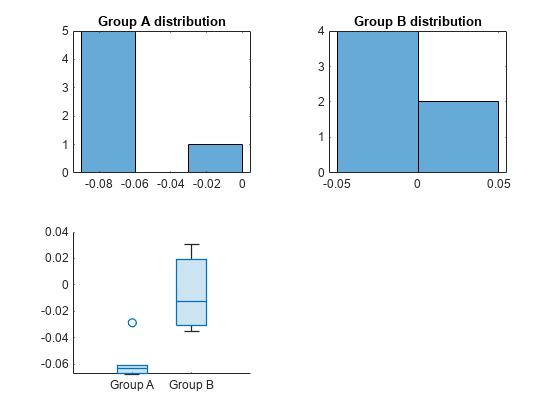

run_paired_comparison(task_coeffs(2,:), task_coeffs(3,:))

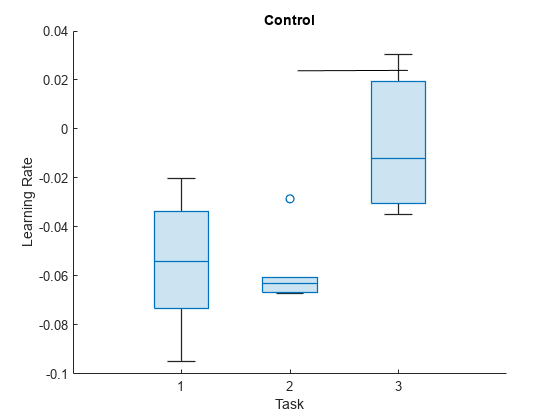


figure
boxchart(task_coeffs')

learning_rates_ctrl = task_coeffs;

## Learning Rate Comparison (Experimental)

AD test for group A: 0, p=0.755
AD test for group B: 0, p=0.703
Both data are parametric
Found and removed 0 outliers
Paired-Sample t-Test Results
	h=0
	p=0.134
	N=6
Difference is not significant


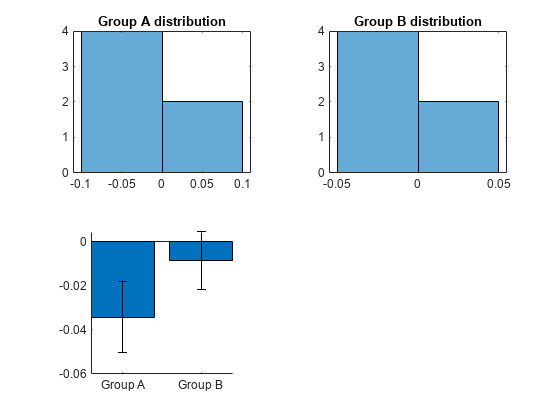

MODEL_SEED = [0.6, -0.2];

task_coeffs = [];
for task_idx = 1:3
    rmse_tbt_aggregate = [];
    for i=1:list_length
        rmse_tbt_aggregate = [rmse_tbt_aggregate, participants(i).task_results(task_idx).rmse.expl.int_a, participants(i).task_results(task_idx).rmse.expl.int_b];
    end

    fig_data = rmse_tbt_aggregate;
    [n_trials, n_series] = size(fig_data);
    for i=1:n_series
        fitted_model = fit((1:1:n_trials)',fig_data(:,i),'exp1', 'StartPoint', MODEL_SEED);
        coeffs = coeffvalues(fitted_model);
        task_coeffs(task_idx,i) = coeffs(2);
    end
end

figure
run_paired_comparison(task_coeffs(2, :), task_coeffs(1, :))

AD test for group A: 0, p=0.187
AD test for group B: 1, p=0.017
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=0
	p=0.062
	N=12
Difference is not significant


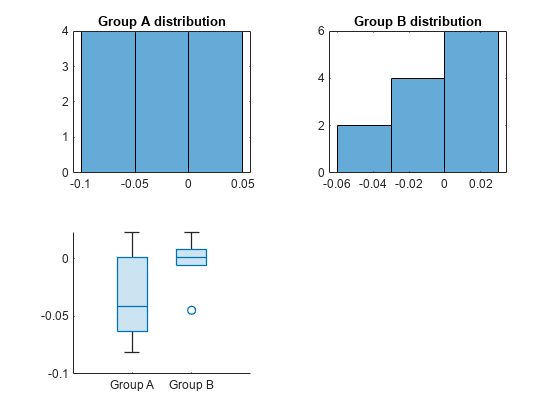

run_paired_comparison([task_coeffs(2,:),task_coeffs(2,:)], [task_coeffs(3,:),task_coeffs(3,:)])

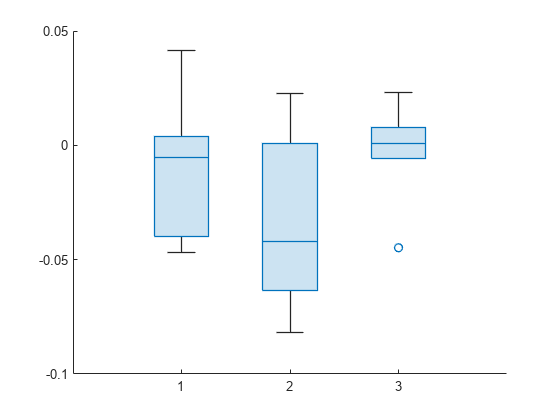


figure
boxchart(task_coeffs')

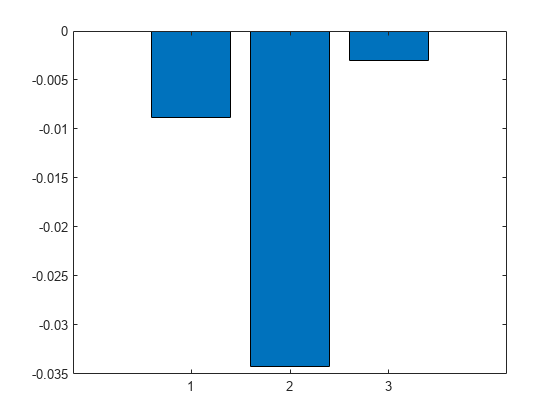

learning_rates_expl = task_coeffs;
figure
bar(mean(learning_rates_expl, 2))

## Learning Rate Comparison (Control Vs. Experimental)

AD test for group A: 1, p=0.002
AD test for group B: 0, p=0.755
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=0
	p=0.156
	N=6
Difference is not significant


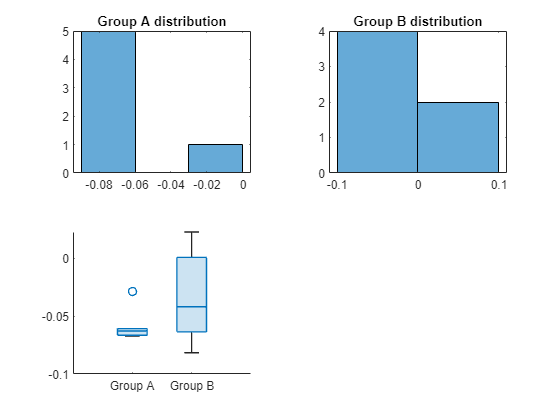

run_paired_comparison(learning_rates_ctrl(2,:), learning_rates_expl(2,:))

AD test for group A: 0, p=0.794
AD test for group B: 0, p=0.703
Both data are parametric
Found and removed 0 outliers
Paired-Sample t-Test Results
	h=0
	p=0.102
	N=6
Difference is not significant


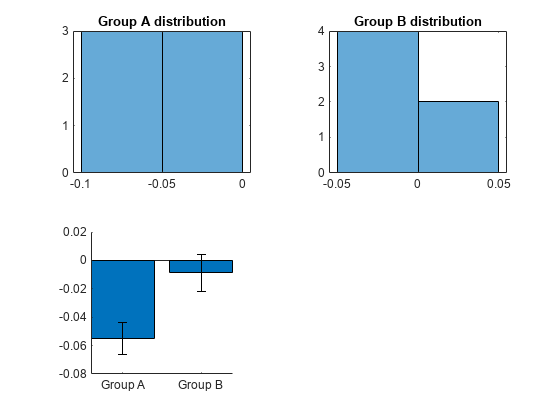

run_paired_comparison(learning_rates_ctrl(1,:), learning_rates_expl(1,:))

### Learning Effect (Control)

AD test for group A: 1, p=0.008
AD test for group B: 0, p=0.263
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=1
	p=0.034
	N=24
Difference is significant


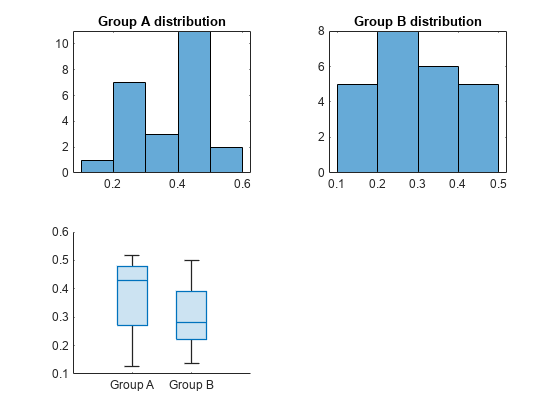

AD test for group A: 0, p=0.214
AD test for group B: 1, p=0.034
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=1
	p=0.000
	N=24
Difference is significant


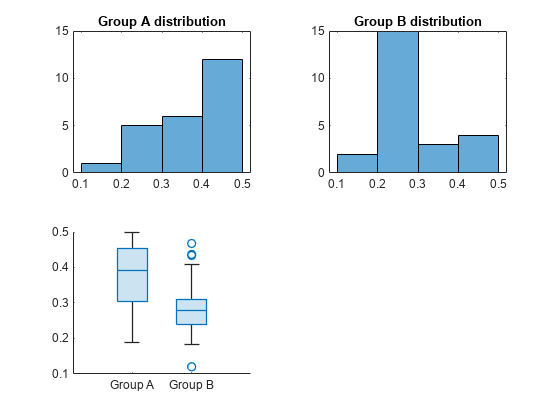

AD test for group A: 1, p=0.001
AD test for group B: 0, p=0.163
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=0
	p=0.361
	N=24
Difference is not significant


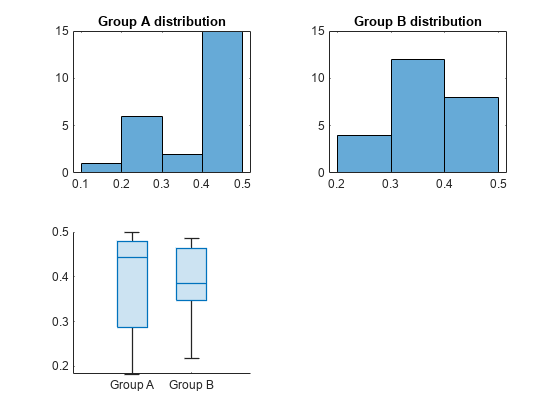

for task_idx = 1:3
rmse_first = [];
rmse_last = [];
for i=1:list_length
    task_rmse = participants(i).task_results(task_idx).rmse.ctrl;
    rmse_first = [   rmse_first;
                    task_rmse.int_a(1:4)';
                    task_rmse.int_b(1:4)'];
    rmse_last = [   rmse_last;
                    task_rmse.int_a(end-3:end)';
                    task_rmse.int_b(end-3:end)'];
end
run_paired_comparison(reshape(rmse_first',[],1), reshape(rmse_last',[],1))
mean_rmse_first = mean(rmse_first, 2);
mean_rmse_last = mean(rmse_last, 2);
learning_effect_ctrl(task_idx,:) = (mean_rmse_first - mean_rmse_last)';
end
figure
boxchart(learning_effect_ctrl')
figure

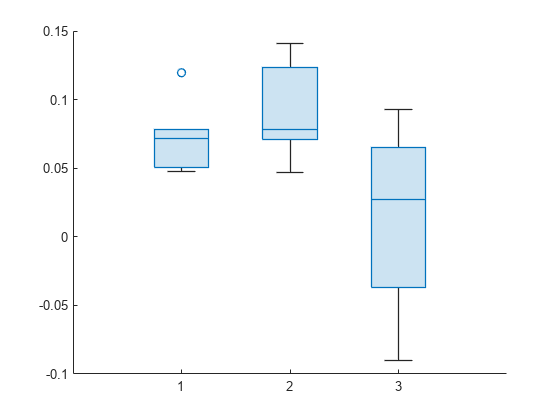

bar(mean(learning_effect_ctrl, 2))
run_paired_comparison(learning_effect_ctrl(2,:), learning_effect_ctrl(1,:))

run_paired_comparison(learning_effect_ctrl(2,:), learning_effect_ctrl(3,:))

### Learning Effect (Experimental)

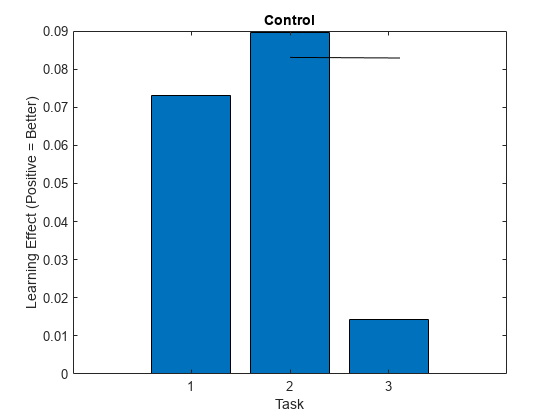

for task_idx = 1:3

AD test for group A: 0, p=0.352
AD test for group B: 0, p=0.306
Both data are parametric
Found and removed 1 outliers
Paired-Sample t-Test Results
	h=0
	p=0.269
	N=5
Difference is not significant


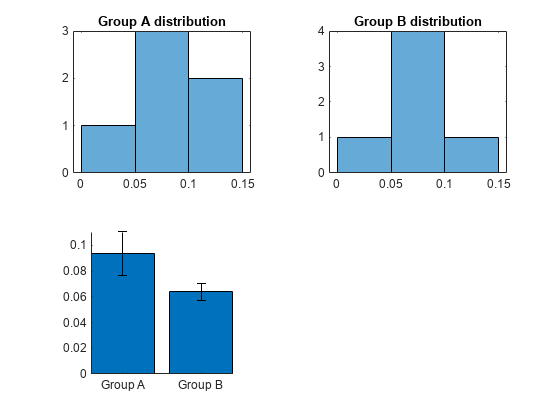

rmse_first = [];

AD test for group A: 0, p=0.352
AD test for group B: 0, p=0.855
Both data are parametric
Found and removed 0 outliers
Paired-Sample t-Test Results
	h=1
	p=0.022
	N=6
Difference is significant


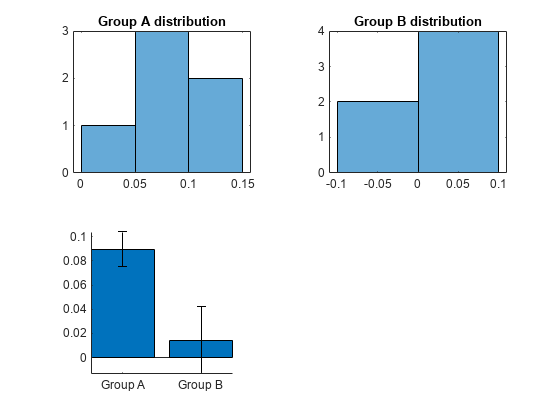

rmse_last = [];

AD test for group A: 0, p=0.358
AD test for group B: 1, p=0.005
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=0
	p=0.932
	N=24
Difference is not significant


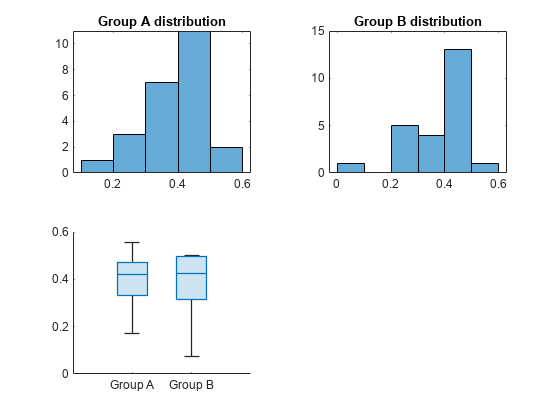

AD test for group A: 0, p=0.190
AD test for group B: 0, p=0.596
Both data are parametric
Found and removed 0 outliers
Paired-Sample t-Test Results
	h=1
	p=0.017
	N=24
Difference is significant


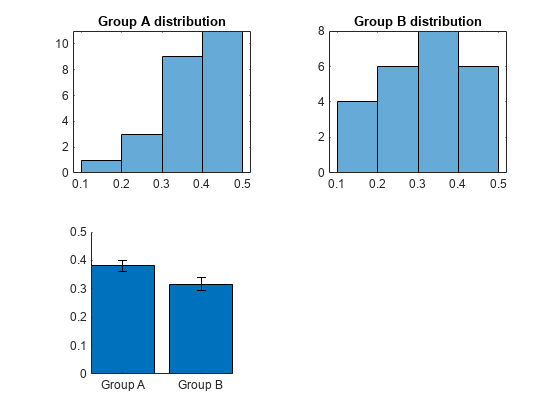

AD test for group A: 1, p=0.009
AD test for group B: 1, p=0.004
At least one group's data are not parametric
Wilcoxon signed rank test Results
	h=0
	p=0.808
	N=24
Difference is not significant


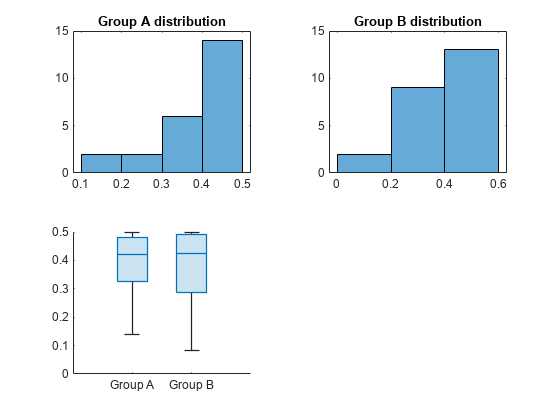

for i=1:list_length
    task_rmse = participants(i).task_results(task_idx).rmse.expl;
    rmse_first = [   rmse_first;
                    task_rmse.int_a(1:4)';
                    task_rmse.int_b(1:4)'];
    rmse_last = [   rmse_last;
                    task_rmse.int_a(end-3:end)';
                    task_rmse.int_b(end-3:end)'];
end
run_paired_comparison(reshape(rmse_first',[],1), reshape(rmse_last',[],1))
mean_rmse_first = mean(rmse_first, 2);
mean_rmse_last = mean(rmse_last, 2);
learning_effect_expl(task_idx,:) = (mean_rmse_first - mean_rmse_last)';
end
figure
boxchart(learning_effect_expl')
figure
bar(mean(learning_effect_expl, 2))
run_paired_comparison(learning_effect_expl(2,:), learning_effect_expl(1,:))

run_paired_comparison(learning_effect_expl(2,:), learning_effect_expl(3,:))

#### Control: First - Last (4 point difference)

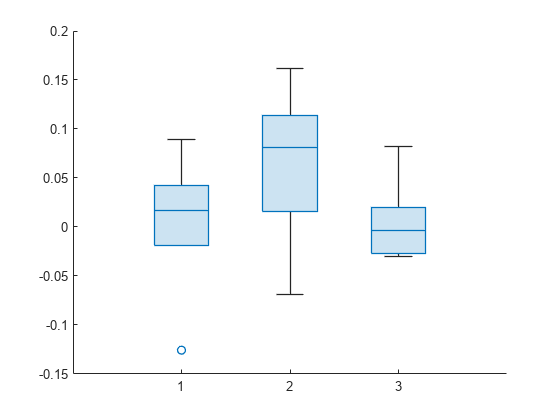

run_paired_comparison(control_rmse_data(:,1), control_rmse_data(:,2))

AD test for group A: 0, p=0.764
AD test for group B: 0, p=0.513
Both data are parametric
Found and removed 1 outliers
Paired-Sample t-Test Results
	h=1
	p=0.010
	N=5
Difference is significant


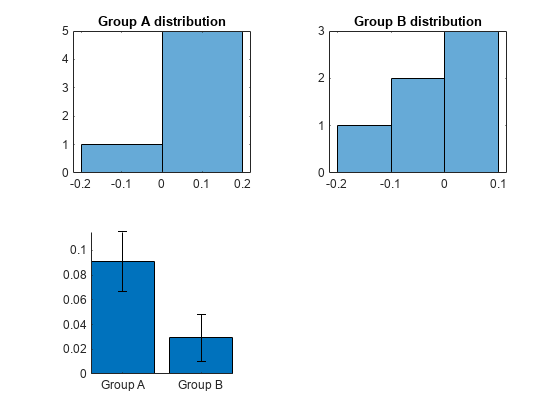

l_effect_cl_control = [mean(control_rmse_data(1:8,1)-control_rmse_data(1:8,2));

AD test for group A: 0, p=0.764
AD test for group B: 0, p=0.178
Both data are parametric
Found and removed 0 outliers
Paired-Sample t-Test Results
	h=0
	p=0.263
	N=6
Difference is not significant


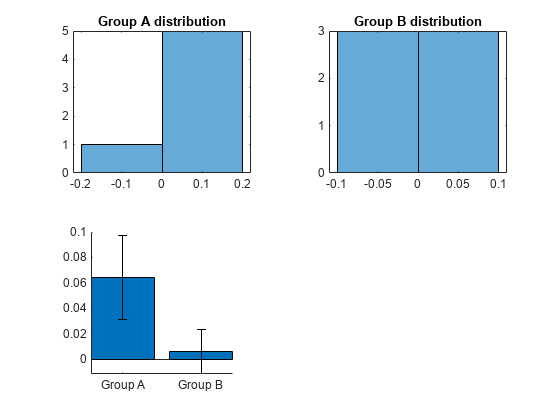

    mean(control_rmse_data(9:16,1)-control_rmse_data(9:16,2));

    mean(control_rmse_data(17:24,1)-control_rmse_data(17:24,2))]

experiment_rmse_data = [];
for i=1:list_length
    temp = [participants(i).task_results(2).rmse.expl.int_a(1:4), participants(i).task_results(2).rmse.expl.int_a(end-3:end)];
    experiment_rmse_data = [experiment_rmse_data; temp];
    temp = [participants(i).task_results(2).rmse.expl.int_b(1:4), participants(i).task_results(2).rmse.expl.int_b(end-3:end)];
    experiment_rmse_data = [experiment_rmse_data; temp];
end

run_paired_comparison(experiment_rmse_data(:,1), experiment_rmse_data(:,2))

l_effect_cl_experiment = [mean(experiment_rmse_data(1:8,1)-experiment_rmse_data(1:8,2));
    mean(experiment_rmse_data(9:16,1)-experiment_rmse_data(9:16,2));
    mean(experiment_rmse_data(17:24,1)-experiment_rmse_data(17:24,2))]

### Human Learning Effect

control_rmse_data = [];
for i=1:list_length
    temp = [participants(i).task_results(3).rmse.ctrl.int_a(1:4), participants(i).task_results(3).rmse.ctrl.int_a(end-3:end)];
    control_rmse_data = [control_rmse_data; temp];
    temp = [participants(i).task_results(3).rmse.ctrl.int_b(1:4), participants(i).task_results(3).rmse.ctrl.int_b(end-3:end)];
    control_rmse_data = [control_rmse_data; temp];
end

run_paired_comparison(control_rmse_data(:,1), control_rmse_data(:,2))

l_effect_hl_control = [mean(control_rmse_data(1:8,1)-control_rmse_data(1:8,2));
    mean(control_rmse_data(9:16,1)-control_rmse_data(9:16,2));
    mean(control_rmse_data(17:24,1)-control_rmse_data(17:24,2))]

experiment_rmse_data = [];
for i=1:list_length
    temp = [participants(i).task_results(3).rmse.expl.int_a(1:4), participants(i).task_results(3).rmse.expl.int_a(end-3:end)];
    experiment_rmse_data = [experiment_rmse_data; temp];
    temp = [participants(i).task_results(3).rmse.expl.int_b(1:4), participants(i).task_results(3).rmse.expl.int_b(end-3:end)];
    experiment_rmse_data = [experiment_rmse_data; temp];
end

run_paired_comparison(experiment_rmse_data(:,1), experiment_rmse_data(:,2))

l_effect_hl_experiment = [mean(experiment_rmse_data(1:8,1)-experiment_rmse_data(1:8,2));
    mean(experiment_rmse_data(9:16,1)-experiment_rmse_data(9:16,2));
    mean(experiment_rmse_data(17:24,1)-experiment_rmse_data(17:24,2))]

## Learning Effect Comparison

run_nonparam_paired_test(l_effect_hl_control, l_effect_cl_control)
run_nonparam_paired_test(l_effect_hl_experiment, l_effect_cl_experiment)

disp('H')

## par int

t1_rmse_avg_expl = [];
t2_rmse_avg_expl = [];
t3_rmse_avg_expl = [];
for i=1:list_length
    t1_rmse_avg_expl = [t1_rmse_avg_expl; mean(participants(i).participant_results(1).rmse.expl.int_a); mean(participants(i).participant_results(1).rmse.expl.int_b)];
    t2_rmse_avg_expl = [t2_rmse_avg_expl; mean(participants(i).participant_results(2).rmse.expl.int_a); mean(participants(i).participant_results(2).rmse.expl.int_b)];
    t3_rmse_avg_expl = [t3_rmse_avg_expl; mean(participants(i).participant_results(3).rmse.expl.int_a); mean(participants(i).participant_results(3).rmse.expl.int_b)];
end

run_paired_comparison(t2_rmse_avg_expl, t1_rmse_avg_expl)
run_paired_comparison(t2_rmse_avg_expl, t3_rmse_avg_expl)

## par xint

t1_rmse_avg_expl = [];
t2_rmse_avg_expl = [];
t3_rmse_avg_expl = [];
for i=1:list_length
    t1_rmse_avg_expl = [t1_rmse_avg_expl; mean(participants(i).participant_results(1).rmse.expl.xint_a); mean(participants(i).participant_results(1).rmse.expl.xint_b)];
    t2_rmse_avg_expl = [t2_rmse_avg_expl; mean(participants(i).participant_results(2).rmse.expl.xint_a); mean(participants(i).participant_results(2).rmse.expl.xint_b)];
    t3_rmse_avg_expl = [t3_rmse_avg_expl; mean(participants(i).participant_results(3).rmse.expl.xint_a); mean(participants(i).participant_results(3).rmse.expl.xint_b)];
end

run_paired_comparison(t2_rmse_avg_expl, t1_rmse_avg_expl)
run_paired_comparison(t2_rmse_avg_expl, t3_rmse_avg_expl)

## xpar int

t1_rmse_avg_ctrl = [];
t2_rmse_avg_ctrl = [];
t3_rmse_avg_ctrl = [];
for i=1:list_length
    t1_rmse_avg_ctrl = [t1_rmse_avg_ctrl; mean(participants(i).participant_results(1).rmse.ctrl.int_a); mean(participants(i).participant_results(1).rmse.ctrl.int_b)];
    t2_rmse_avg_ctrl = [t2_rmse_avg_ctrl; mean(participants(i).participant_results(2).rmse.ctrl.int_a); mean(participants(i).participant_results(2).rmse.ctrl.int_b)];
    t3_rmse_avg_ctrl = [t3_rmse_avg_ctrl; mean(participants(i).participant_results(3).rmse.ctrl.int_a); mean(participants(i).participant_results(3).rmse.ctrl.int_b)];
end

run_paired_comparison(t2_rmse_avg_ctrl, t1_rmse_avg_ctrl)
run_paired_comparison(t2_rmse_avg_ctrl, t3_rmse_avg_ctrl)

## xpar xint

t1_rmse_avg_ctrl = [];
t2_rmse_avg_ctrl = [];
t3_rmse_avg_ctrl = [];
for i=1:list_length
    t1_rmse_avg_ctrl = [t1_rmse_avg_ctrl; mean(participants(i).participant_results(1).rmse.ctrl.xint_a); mean(participants(i).participant_results(1).rmse.ctrl.xint_b)];
    t2_rmse_avg_ctrl = [t2_rmse_avg_ctrl; mean(participants(i).participant_results(2).rmse.ctrl.xint_a); mean(participants(i).participant_results(2).rmse.ctrl.xint_b)];
    t3_rmse_avg_ctrl = [t3_rmse_avg_ctrl; mean(participants(i).participant_results(3).rmse.ctrl.xint_a); mean(participants(i).participant_results(3).rmse.ctrl.xint_b)];
end

run_paired_comparison(t2_rmse_avg_ctrl, t1_rmse_avg_ctrl)
run_paired_comparison(t2_rmse_avg_ctrl, t3_rmse_avg_ctrl)

t2_rmse_avg_expl = [];
t3_rmse_avg_expl = [];

for i=1:length(participants)
    t2_rmse_avg_expl = [t2_rmse_avg_expl; mean(participants(i).participant_results(2).rmse.expl.int_a); mean(participants(i).participant_results(2).rmse.expl.int_b)];
    t3_rmse_avg_expl = [t3_rmse_avg_expl; mean(participants(i).participant_results(3).rmse.expl.int_a); mean(participants(i).participant_results(3).rmse.expl.int_b)];
end

run_paired_comparison(t2_rmse_avg_expl, t3_rmse_avg_expl)

t1_slopes = [];
t2_slopes = [];
t3_slopes = [];
for i=1:length(participants)
    t1_slopes = [t1_slopes; participants(i).participant_results(1).rmse_slopes.expl.xint_a(1); participants(i).participant_results(1).rmse_slopes.expl.xint_b(1)];
    t2_slopes = [t2_slopes; participants(i).participant_results(2).rmse_slopes.expl.xint_a(1); participants(i).participant_results(2).rmse_slopes.expl.xint_b(1)];
    t3_slopes = [t3_slopes; participants(i).participant_results(3).rmse_slopes.expl.xint_a(1); participants(i).participant_results(3).rmse_slopes.expl.xint_b(1)];
end

run_paired_comparison(t2_slopes, t3_slopes)

function run_paired_comparison(group_a, group_b)
figure
tlo = tiledlayout('flow');
nexttile; histogram(group_a); title("Group A distribution")
nexttile; histogram(group_b); title("Group B distribution")
if and(length(group_a)>=4, length(group_b)>=4) % AD test needs at least 4 datapoints
    [ad_results_a, p] = adtest(group_a);
    fprintf("AD test for group A: %d, p=%0.3f\n", ad_results_a, p);
    [ad_results_b, p] = adtest(group_b);
    fprintf("AD test for group B: %d, p=%0.3f\n", ad_results_b, p);
    parametric_condition = and(ad_results_a==0, ad_results_b==0);
else
    fprintf("At least one group has less than 4 data points.\r\nDefaulting to nonparametric comparison.")
    parametric_condition = false;
end
if(parametric_condition)
    fprintf("Both data are parametric\n");
    group_a_outliers = isoutlier(group_a, 'quartiles');
    group_b_outliers = isoutlier(group_b, 'quartiles');
    combined_outliers = or(group_a_outliers, group_b_outliers);
    fprintf("Found and removed %d outliers\n", sum(combined_outliers));
    [h, p] = ttest(group_a(combined_outliers~=1), group_b(combined_outliers~=1));
    fprintf("Paired-Sample t-Test Results\n\th=%d\n\tp=%0.3f\n\tN=%d\n", h, p, sum(~combined_outliers));
    if h
        fprintf("Difference is significant\n");
    else
        fprintf("Difference is not significant\n");
    end
    nexttile
    plot_bar(group_a(combined_outliers~=1), group_b(combined_outliers~=1))
else
    fprintf("At least one group's data are not parametric\n");
    [p,h] = signrank(group_a, group_b);
    fprintf("Wilcoxon signed rank test Results\n\th=%d\n\tp=%0.3f\n\tN=%d\n", h, p, length(group_a));
    if h
        fprintf("Difference is significant\n");
    else
        fprintf("Difference is not significant\n");
    end
    nexttile
    plot_box(group_a, group_b)
end
end

function run_unpaired_comparison(group_a, group_b)
error("this function has not been implemented yet")
figure
tlo = tiledlayout('flow');
nexttile; histogram(group_a); title("Group A distribution")
nexttile; histogram(group_b); title("Group B distribution")
if and(length(group_a)>=4, length(group_b)>=4) % AD test needs at least 4 datapoints
    [ad_results_a, p] = adtest(group_a);
    fprintf("AD test for group A: %d, p=%0.3f\n", ad_results_a, p);
    [ad_results_b, p] = adtest(group_b);
    fprintf("AD test for group B: %d, p=%0.3f\n", ad_results_b, p);
    parametric_condition = and(ad_results_a==0, ad_results_b==0);
else
    fprintf("At least one group has less than 4 data points.\r\nDefaulting to nonparametric comparison.")
    parametric_condition = false;
end
if(parametric_condition)
    fprintf("Both data are parametric\n");
    group_a_outliers = isoutlier(group_a, 'quartiles');
    group_b_outliers = isoutlier(group_b, 'quartiles');
    combined_outliers = or(group_a_outliers, group_b_outliers);
    fprintf("Found and removed %d outliers\n", sum(combined_outliers));
    [h, p] = ttest(group_a(combined_outliers~=1), group_b(combined_outliers~=1));
    fprintf("Paired-Sample t-Test Results\n\th=%d\n\tp=%0.3f\n\tN=%d\n", h, p, sum(~combined_outliers));
    if h
        fprintf("Difference is significant\n");
    else
        fprintf("Difference is not significant\n");
    end
    nexttile
    plot_bar(group_a(combined_outliers~=1), group_b(combined_outliers~=1))
else
    fprintf("At least one group's data are not parametric\n");
    [p,h] = signrank(group_a, group_b);
    fprintf("Wilcoxon signed rank test Results\n\th=%d\n\tp=%0.3f\n\tN=%d\n", h, p, length(group_a));
    if h
        fprintf("Difference is significant\n");
    else
        fprintf("Difference is not significant\n");
    end
    nexttile
    plot_box(group_a, group_b)
end
end

function plot_bar(group_a, group_b)
group_a_mean = mean(group_a);
group_a_sem = std(group_a)/sqrt(length(group_a));
group_b_mean = mean(group_b);
group_b_sem = std(group_b)/sqrt(length(group_b));

x=1:2;
data = [group_a_mean group_b_mean]';
errhigh = [group_a_sem, group_b_sem];
errlow  = errhigh;

bar(x, data)

hold on

er = errorbar(x, data, errlow, errhigh);
er.Color = [0 0 0];
er.LineStyle = 'none';

hold off
box off
axis square

xticklabels({'Group A', 'Group B'})
% xlabel("sEMG Type")
% ylabel('Average RMSE')
% title({"Intended Movements",""})
end

function plot_box(group_a, group_b)
data = [reshape(group_a, [length(group_a), 1]), reshape(group_b, [length(group_b), 1])];
boxchart(data)
xticklabels({'Group A', 'Group B'})
end

function fh = plot_aggregate_rmse_ctrl(participants, task_idx, series_title, series_color, l_style)
list_length = length(participants);
MODEL_SEED = [0.6, -0.2];
rmse_tbt_aggregate = [];

for i=1:list_length
    rmse_tbt_aggregate = [rmse_tbt_aggregate, participants(i).task_results(task_idx).rmse.ctrl.int_a,participants(i).task_results(task_idx).rmse.ctrl.int_b];
end

fig_data = rmse_tbt_aggregate';                                            % Create Data
adt_data = mat2cell(fig_data, size(fig_data,1), ones(1,size(fig_data,2)));                 % Split Into Cells By Column
[h, p] = cellfun(@adtest, adt_data);                                     % Perform ,adtest  On Each Cell Column

fh = figure;
sprintf("AD test: %d", any(h))
    boxplot(fig_data, 'PlotStyle', 'compact', Colors=series_color)
    [~, n_trials] = size(fig_data);
    model_fit = fit((1:1:n_trials)', median(fig_data,1)', 'exp1', 'StartPoint', MODEL_SEED);
    hold on
    plot(model_fit, l_style);
    hold off

title(series_title)
ylim([0 0.6])
ylabel('RMSE')
xlabel('Trial #')
box off
grid on
end

function fh = plot_aggregate_rmse_expl(participants, task_idx, series_title, series_color, l_style)
list_length = length(participants);
MODEL_SEED = [0.6, -0.2];
rmse_tbt_aggregate = [];

for i=1:list_length
    rmse_tbt_aggregate = [rmse_tbt_aggregate, participants(i).task_results(task_idx).rmse.expl.int_a,participants(i).task_results(task_idx).rmse.expl.int_b];
end

fig_data = rmse_tbt_aggregate';                                            % Create Data
adt_data = mat2cell(fig_data, size(fig_data,1), ones(1,size(fig_data,2)));                 % Split Into Cells By Column
[h, p] = cellfun(@adtest, adt_data);                                     % Perform ,adtest  On Each Cell Column
sprintf("AD test: %d", any(h))
fh = figure;
boxplot(fig_data, 'PlotStyle', 'compact', Colors=series_color)
[~, n_trials] = size(fig_data);
model_fit = fit((1:1:n_trials)', median(fig_data,1)', 'exp1', 'StartPoint', MODEL_SEED);
hold on
plot(model_fit, l_style);
hold off
title(series_title)
ylim([0 0.6])
ylabel('RMSE')
xlabel('Trial #')
box off
grid on
end